# Bioreactor Optimization and Parameter Estimation for Reaction Kinetics

## Computational Tools Needed

MATLAB, Optimization Toolbox, Global Optimization Toolbox, Curve Fitting Toolbox

## Learning Objectives

- Optimizing bioreactor operation by identifying free variables, objective function and implementing the solution using MATLAB and Global Optimization Toolbox.

- Estimating reaction kinetics parameters from concentration and rate data using MATLAB, Curve Fitting Toolbox and Optimization Toolbox.

- Setting up optimization problems programmatically and interactively using Live Tasks.

## Bioreactor Optimization

Let's revisit "Bacteria Growth in a Batch Reactor" exercise. In this exercise, we manually changed the initial conditions like the initial concentration of cells and substrate and observed how the cell concentration, substrate concentration, product concentration and the cell growth rate with inhibition changed over time. Now, let's focus on how we can change the initial cell concentration and the initial substrate concentration for a given range values such that we achieve the maximum product concentration. This is an optimization problem and we will solve this problem using MATLAB and Optimization Toolbox. 

- Optimization problems require an objective function. 

- In order to have an optimization problem, we need to have free variables. If the degrees of freedom is 0, it means the problem may have a unique solution and it is not an optimization problem. In this case, we have free variables, the initial conditions of the concentrations that we can freely change to fulfill our objective function.

- We will impose constraints i.e. upper and lower bounds for the concentrations and we will seek a maximum in such a way that the constraints are satisfied.

 **Exercise 1: **Modify the code from "Bacteria Growth in a Batch Reactor" into an optimization problem. Use the cell and substrate concentration lower and upper bounds and time span given below. The objective is maximizing the product concentration, $C_p$. Use [surrogateopt ](https://www.mathworks.com/help/gads/surrogateopt.html)to optimize the objective function. Keep in mind that this function solves a minimization problem. Since we want to maximize our function, the objective function must be multiplied with -1. The maximum product concentration can occur at anytime in the timespan. Make sure to pick the maximum value in the timespan. Generate the same plots as "Bacteria Growth in a Batch Reactor" for the optimized values of the initial conditions and the optimized product concentration.

Scalar objective function
Number of variables: 2
Number of integer constraints: 0
Number of linear inequality constraints: 0
Number of linear equality constraints: 0
Number of nonlinear inequality constraints: 0

F-count       Time        Best          Current         Trial
             (seconds)    Fval          Fval            type
   1         1.17      -4.3992e+00     -4.3992e+00   random 
   2         2.19      -9.3001e+01     -9.3001e+01   random 
   3         2.37      -9.3001e+01     -5.8177e+01   random 
   4         2.49      -9.3017e+01     -9.3017e+01   random 
   5         2.63      -9.3017e+01     -9.3000e+01   random 
   6         2.88      -9.3017e+01     -3.1446e+01   random 
   7         2.97      -9.3017e+01     -9.2999e+01   random 
   8         2.99      -9.3017e+01     -8.3718e+01   random 
   9         3.07      -9.3017e+01     -9.3000e+01   random 
  10         3.08      -9.3017e+01     -9.2557e+01   random 
  11         3.10      -9.3017e+01     -9.2948e+01   r

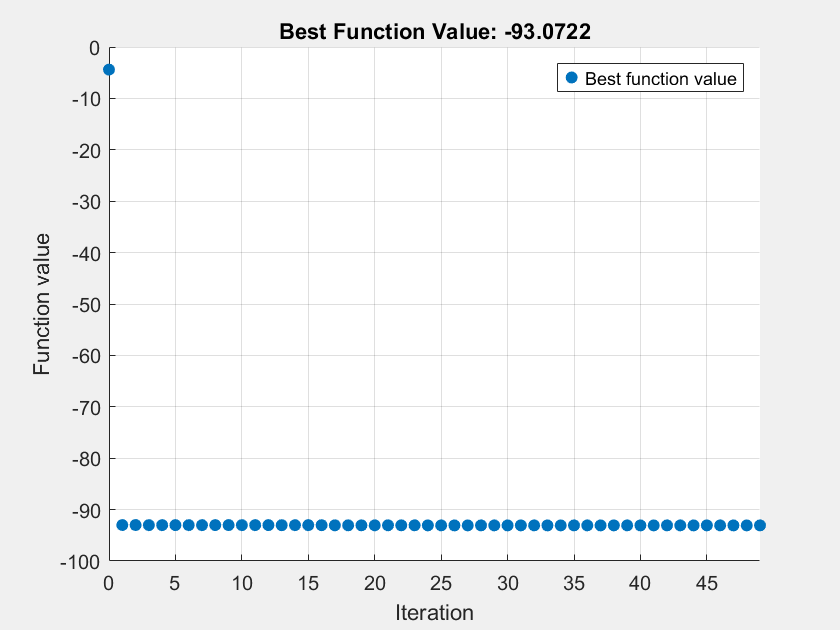

% Parameters
Cpstar = 93;
n = 0.52;
Ysc = 1/0.08;
Ypc = 5.6;
mumax = 0.33;
Ks = 1.7;
kd = 0.01;
m = 0.03;

% Time span
tspan = [0 30];

% Bounds for [Cc0, Cs0]
Cc0_lb = 0.1;  Cc0_ub = 200;
Cs0_lb = 10;   Cs0_ub = 500;

% Objective: negative max Cp
objfun = @(x) -getMaxCp(x, tspan, Cpstar, n, Ysc, Ypc, mumax, Ks, kd, m);

% Run surrogate optimization
[xopt, fval] = surrogateopt(objfun, ...
    [Cc0_lb, Cs0_lb], [Cc0_ub, Cs0_ub], ...
    optimoptions('surrogateopt', 'MaxFunctionEvaluations', 50, 'Display', 'iter'));

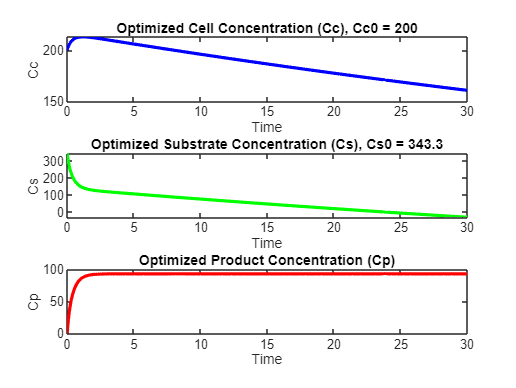


optCc0 = xopt(1);
optCs0 = xopt(2);

% Solve ODE with optimal initial conditions
[t, Y] = ode45(@(t, Y) odefun(t, Y, Cpstar, n, Ysc, Ypc, mumax, Ks, kd, m), tspan, [optCc0, optCs0, 0]);

% Plot results
figure;
subplot(3,1,1); plot(t, Y(:,1), 'b', 'LineWidth', 2);
title(['Optimized Cell Concentration (Cc), Cc0 = ', num2str(optCc0,3)]);
xlabel('Time'); ylabel('Cc');

subplot(3,1,2); plot(t, Y(:,2), 'g', 'LineWidth', 2);
title(['Optimized Substrate Concentration (Cs), Cs0 = ', num2str(optCs0,4)]);
xlabel('Time'); ylabel('Cs');

subplot(3,1,3); plot(t, Y(:,3), 'r', 'LineWidth', 2);
title('Optimized Product Concentration (Cp)');
xlabel('Time'); ylabel('Cp');

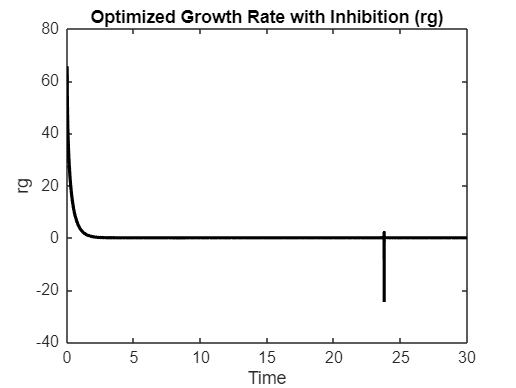


% Plot growth rate
figure;
rg = mumax * (Y(:,1) .* Y(:,2) ./ (Ks + Y(:,2))) .* (1 - (Y(:,3) / Cpstar).^n);
plot(t, rg, 'k', 'LineWidth', 2);
title('Optimized Growth Rate with Inhibition (rg)');
xlabel('Time'); ylabel('rg');


[maxCpVal, idx] = max(Y(:,3));
disp(['Maximum Cp: ', num2str(maxCpVal,4), ' at time t = ', num2str(t(idx),3)]);

Maximum Cp: 93.07 at time t = 23.8


disp(['Optimal Cc0: ', num2str(optCc0,3), ', Optimal Cs0: ', num2str(optCs0,4)]);

Optimal Cc0: 200, Optimal Cs0: 343.3



% --- Supporting Functions ---
function maxCp = getMaxCp(x, tspan, Cpstar, n, Ysc, Ypc, mumax, Ks, kd, m)
    [~, Y] = ode45(@(t, Y) odefun(t, Y, Cpstar, n, Ysc, Ypc, mumax, Ks, kd, m), tspan, [x(1), x(2), 0]);
    maxCp = max(Y(:,3));
end

function dYdt = odefun(~, Y, Cpstar, n, Ysc, Ypc, mumax, Ks, kd, m)
    Cc = Y(1); Cs = Y(2); Cp = Y(3);
    rg = mumax * (Cc * Cs / (Ks + Cs)) * (1 - (Cp / Cpstar)^n);
    dCc_dt = rg - kd * Cc;
    dCs_dt = -Ysc * rg - m * Cc;
    dCp_dt = Ypc * rg;
    dYdt = [dCc_dt; dCs_dt; dCp_dt];
end

  ** Try: **

- What happens if you change the initial cell and substrate conditions' lower and upper bounds? 

- Do you need an initial guess for surrogate function to solve the optimization problem?

- What happens if you change the optimization options?

## Parameter Estimation for Reaction Kinetics

In the previous exercises, we used parameters like $Y_{s|c}$, $Y_{p|c}$, $\mu_{\max }$ and $K_s$. Typically, in the reaction kinetics experiments, concentrations are measured and these parameters are estimated using concentration vs. time data and with the aid of some equations. In this section, we will learn how to do parameter estimation using reaction kinetics data. We will use MATLAB and Curve Fitting Toolbox. 

 **Exercise 2: **The following data is obtained in a batch reactor. Assume that there is no lag and maintenance at the start of the growth is negligible. Using the data and the listed equations, estimate $Y_{c|s}$

 $C_c =Y_{c|s} \left(C_{\textrm{s0}} -C_s \right)$           **(Equation 1)**

**Reaction Kinetics Data:**


$$\textrm{Substrate}+\textrm{Cells}\to \textrm{More}\;\textrm{cells}+\textrm{Product}$$


%Synthetically generate experimental data for Cc to obtain Ycs by curve
%fitting.
clear vars; 
n=10;
time= linspace(0,3,n)';
Ytrue=0.063;
Cs0 = 220;
Cs=linspace(Cs0,200,n)';
delta_Cs=Cs0-Cs;
noise=0.01*rand(n,1);
Cc=Ytrue * delta_Cs .* (1 + noise);



Calculate $Y_{c|s} \;$from the reaction data given above using Equation 1.

** Interactive exercise:**

- Now that we have $\Delta C_s$, let's navigate to MATLAB Apps tab -> Curve Fitter.  In Curve Fitter app, click on "Select Data", select "deltaCs" as x-data and Cc as y-data, hit "Close". Select "Custom Equation" in Regression Models and enter your custom equation i.e. y=a*x to obtain $Y_{c|s}$  You will see fit results in the "Results" tab along with Goodness of Fit information. You can export the results or generate a code if you like to apply this model to a different dataset. "Generate Code" and explore autogenerated code. 

 **Exercise 3: **Using the reaction data and Equation 2 below, estimate $\mu_{\max }$ and $K_s$. To estimate these parameters, navigate to "Insert" tab in Live Editor, select "Live Task" in the toolstrip, and search for "Optimize". In the Optimize Live Task, select "Problem-based" approach, create optimization variables   $0\ldotp 0001<\mu_{\max } <5$ and $0\ldotp 0001<K_s <3$. In "Define Problem" section, select "Solve Equations" and type Equation 2 as follows:

rg-((mumax*Cc.*Cs)./(Ks+Cs))

$r_g -\frac{\mu_{\max } C_c C_s }{K_s +C_s }=0$           **(Equation 2)**

%Synthetically generate experimental data for rg
Kstrue=2.5;
mumaxtrue=0.5;
rg=mumaxtrue*(Cc.*Cs)./(Kstrue+Cs).* (1 +0.1*noise);


% Create optimization variables
Ks2 = optimvar("Ks","LowerBound",0.0001,"UpperBound",3);
mumax2 = optimvar("mumax","LowerBound",0.0001,"UpperBound",5);

% Set initial starting point for the solver
initialPoint.Ks = zeros(size(Ks2));
initialPoint.mumax = zeros(size(mumax2));

% Create problem
problem = eqnproblem;

% Define problem equations
problem.Equations = rg-((mumax2*Cc.*Cs)./(Ks2+Cs)) == 0;

% Display problem information
show(problem);


  EquationProblem : 

	Solve for:
       Ks, mumax


       (extraParams{4} - (((mumax .* extraParams{1}) .* extraParams{2}) ./ (Ks + extraParams{3}))) == zeros(10, 1)

       extraParams


	variable bounds:
       0.0001 <= Ks <= 3

       0.0001 <= mumax <= 5




% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint);


Equation problem has bound constraints. Reformulating as a least squares problem.

Solving problem using lsqnonlin.

Equation solved.

lsqnonlin completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



% Display results
solution

solution = struct with fields:
       Ks: 2.7000
    mumax: 0.5007


reasonSolverStopped

reasonSolverStopped =     EquationSolved


objectiveValue

objectiveValue = 1.0e-03 *

         0
    0.0342
    0.0594
   -0.0925
    0.0314
   -0.0146
   -0.1692
    0.2357
    0.1778
   -0.2249



% Clear variables
clearvars Ks2 mumax2 initialPoint reasonSolverStopped objectiveValue

### **Things to Consider:**

- We can also estimate parameters to differential equations by formulating parameter estimation problem as an optimization problem. You can explore this approach by studying [Fit ODE Parameters Using Optimization Variables](https://www.mathworks.com/help/optim/ug/fit-ode-problem-based-least-squares.html) documentation example. 

- We explored interactive workflows for curve fitting, but you can also do the same tasks programmatically.

## **References**

[1] Fogler, H. Scott. Elements of Chemical Reaction Engineering. Prentice Hall, 2006.

[2][ Fogler, H. Scott Lecture Notes ](https://websites.umich.edu/~elements/6e/lectures/umich.html)